## **MAIN**

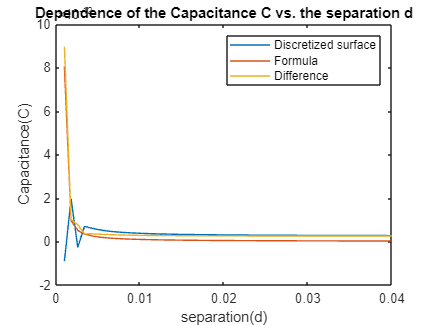


clear
% Npatch_size = 10;
% part3_plot(10);
% part3_plot(20);
% part3_plot(30);
part4(10)

function [C,Q1,Q2] = part2(Npatch_in_width,w,d)

    % Variable initilization
    epsilon0 = 8.85e-12;
    % w = 1e-2; % value from part3
    % d = 3e-3; % value from part3
    Ns1 = Npatch_in_width * Npatch_in_width; % Patch for S1
    Ns2 = Npatch_in_width * Npatch_in_width; % Pathch for S2
    N = Ns1 + Ns2; % Total Patch
    dw = w/Npatch_in_width; % width of single patch
    V0 = 1; % Initial Voltage
    
    % Construct the rm and rn
    d_bottom = 0;
    d_top = d_bottom + d;
    rm_top = zeros(Npatch_in_width*Npatch_in_width,3); % (x = 1,y = 2,z = 3) for top plates
    rn_bottom = rm_top; % for bottom plates
    rm_top(:,3) = d_top;
    rn_bottom(:,3) = d_bottom;
    loop_index = 1;
    for x = 1:Npatch_in_width
        for y = 1:Npatch_in_width
                rn_bottom(loop_index,1) = dw*x;
                rm_top(loop_index,1) = dw*x;
                rn_bottom(loop_index,2) = dw*y;
                rm_top(loop_index,2) = dw*y;
                loop_index = loop_index +1;
        end
    end
    rm = [rm_top;rn_bottom];
    
    % Calculate Z vector
    Z = zeros(N,N);
    deltaSn = dw*dw;
    for m = 1:N
        for n = 1:N
            if m ~= n
                Z(m,n) = 1/(4*pi*epsilon0*norm(rm(m,1:3) - rm(n,1:3)));
            elseif ((rm(m,1) == rm(n,1)) && (rm(m,2) == rm(n,2)))
                Z(m,n) = 1/(2*epsilon0*deltaSn)*(-1*d+sqrt(deltaSn/pi + d*d));
            else
                Z(m,n) = 1/(2*epsilon0*sqrt(pi*deltaSn));
            end
        end
    end
    % Q vector
    Q = zeros(N,1);
    % V vector
    V = zeros(N,1);
    V(1:N/2) = V0/2; % Top plate
    V(N/2+1:N) = -V0/2; % Bottom Plate
    
    % Solution:
    Q = Z\V;
    Q1 = Q(1:N/2); % Top charge
    Q2 = Q(N/2+1:N); % botoom charge
    Q1_sum = sum(Q1(1:N/2));
    C = Q1_sum/V0;
end

## Part 3

function part3_plot(Npatch)
    w = 1e-2; % value from part3
    d = 3e-3; % value from part3
    [C,Q1,Q2] = part2(Npatch,w,d);
    Q1_new = reshape(Q1, Npatch, Npatch) ;
    x = 1:1:Npatch;
    y = 1:1:Npatch;
    surf(x,y,Q1_new);
    xlabel('X-axis');
    ylabel('Y-axis');
    zlabel('Charge');
    title(['Surface Charge Distribution, pathch size: ',num2str(Npatch^2)]);
    filename = ['Surface Charge Distribution-pathch size_',num2str(Npatch^2),'.png']
    saveas(gcf, filename);
end


## **Part 4**

function part4(Npatch)
    w = 1e-2; % value from part4
    d = 4e-2; % value from part4
    loop_index = 1;
    epsilon0 = 8.85e-12;
    totalpoints = 50;
    for x = linspace(0.1e-3,d,totalpoints)
        [C,Q1,Q2] = part2(Npatch,w,x);
        C_discret_array(loop_index) = C;
        C_formula_array(loop_index) = epsilon0 * w^2/x;
        C_difference(loop_index) = abs(C-C_formula_array(loop_index));
        loop_index = loop_index + 1;
    end
    separation = linspace(1e-3,d,totalpoints);
    plot(separation,C_discret_array);
    hold on
    plot(separation, C_formula_array);
    plot(separation, C_difference);
    xlabel('separation(d)');
    ylabel('Capacitance(C)');
    title('Dependence of the Capacitance C vs. the separation d');
    legend('Discretized surface','Formula','Difference');
    saveas(gcf, 'Dependence of the Capacitance C vs the separation d.png');
end